

% Konstanten & Parameter
% AEB Parameter
v_min = 0;        % System aktiv ab 0 km/h
v_max = 60 / 3.6;        % System aktiv bis 60 km/h
bremskraft_min = 9.0;    % Vollbremsung mit 9 m/s²
ttc_warnung = 2.0;       % FCW Warnung bei 2.0s
ttc_bremse = 1.2;        % AEB Eingriff bei 1.2s

% Fahrer-Übersteuerung (Override) Schwellwerte
SCHWELLE_LENKUNG = 15;   % Grad (Absolutwert)
SCHWELLE_GAS = 10;       % Gaspedalstellung in %

% Simulations-Parameter
time_step = 0.01;
gesamtzeit = 15;
zeit = 0:time_step:gesamtzeit;

% Fußgänger (Pedestrian)
v_pedestrian = 5 / 3.6;  % 5 km/h
pedestrian_x = 35;       % 35m vor dem Auto
pedestrian_y = -3;       % Startet 3m rechts/links der Fahrbahn

% Auto Initialisierung
auto_x = 0;
auto_y = 0;
v_ego = 50 / 3.6;        % 50 km/h Startgeschwindigkeit

% Daten-Arrays Initialisieren
auto_position_x = zeros(size(zeit));
auto_position_y = zeros(size(zeit));
auto_geschwindigkeit = zeros(size(zeit));

pedestrian_position_x = zeros(size(zeit));
pedestrian_position_y = zeros(size(zeit));

ttc_werte = zeros(size(zeit));
warnung_aktiv = false(size(zeit));
bremse_aktiv = false(size(zeit));
bremskraft = zeros(size(zeit));
driver_override_aktiv = false(size(zeit)); 

% Fahreraktionen (Simulation)
lenkrad_winkel = zeros(size(zeit)); 
gaspedal_pos = zeros(size(zeit));

% Test-Szenario Kommentar entfernen für Eingriff von Fahrer
%  lenkrad_winkel(zeit > 1.5 & zeit < 3.0) = 20; 

%% 3. Initialisieren der Startwerte
auto_position_x(1) = auto_x;
auto_position_y(1) = auto_y;
auto_geschwindigkeit(1) = v_ego;

pedestrian_position_x(1) = pedestrian_x;
pedestrian_position_y(1) = pedestrian_y;

ttc_werte(1) = Inf;

% Hauptsimulation
for i = 2:length(zeit)
   
    % Bewegungen
    v_aktuell = auto_geschwindigkeit(i-1);
    
    % Auto Bewegung
    auto_position_x(i) = auto_position_x(i-1) + (v_aktuell * time_step);
    auto_position_y(i) = 0; 
    
    % Fußgänger Bewegung
    pedestrian_position_x(i) = pedestrian_x; 
    pedestrian_position_y(i) = pedestrian_position_y(i-1) + (v_pedestrian * time_step);
    
    % Sensorik
    
    % TTC Berechnung
    ttc_werte(i) = berechne_ttc(auto_position_x(i), v_aktuell, pedestrian_position_x(i), pedestrian_position_y(i));
    
    % Systemverfügbarkeit
    system_aktiv = pruefe_geschwindigkeitsbereich(v_aktuell, v_min, v_max);
    
    % Fahrer-Übersteuerung
    is_steering = abs(lenkrad_winkel(i)) > SCHWELLE_LENKUNG;
    is_gas = gaspedal_pos(i) > SCHWELLE_GAS;
    
    driver_override = is_steering || is_gas;
    driver_override_aktiv(i) = driver_override; 

    % Kollisionswarnung
    warnung_alt_input = warnung_aktiv(i-1);
    warnung_aktiv(i) = kollisionswarnung(warnung_alt_input, ttc_werte(i), ttc_warnung);
    
    if warnung_aktiv(i) && ~warnung_alt_input
        fprintf('Zeit %.2fs: FCW WARNUNG (Optisch + Akustisch)\n', zeit(i));
    end
    
    % Notbremsung
    bremse_alt_input = bremse_aktiv(i-1);
    kraft_alt_input  = bremskraft(i-1);
    
    [bremse_aktiv(i), bremskraft(i)] = notbremsung(bremse_alt_input, kraft_alt_input, ...
                                                   ttc_werte(i), ttc_bremse, ...
                                                   bremskraft_min, driver_override);
    
    % Fahrzeugreaktion
    if bremse_aktiv(i)
        neue_v = v_aktuell - (bremskraft(i) * time_step);
    else
        neue_v = v_aktuell;
    end
    
    if neue_v < 0; neue_v = 0; end
    auto_geschwindigkeit(i) = neue_v;
end

Zeit 0.73s: FCW WARNUNG (Optisch + Akustisch)


ACHTUNG: Notbremsung eingeleitet (TTC=1.20s)


% Integration tests
fprintf('      START INTEGRATION TESTS\n');

      START INTEGRATION TESTS




% Test 1: Geschwindigkeitsbereich
t1_res = pruefe_geschwindigkeitsbereich(15/3.6, v_min, v_max);
if t1_res == false
    fprintf('[PASS] Test 1: System inaktiv bei 15 km/h.\n');
else
    fprintf('[FAIL] Test 1: System sollte bei 15 km/h inaktiv sein!\n');
end

[FAIL] Test 1: System sollte bei 15 km/h inaktiv sein!



% Test 2: Geschwindigkeitsbereich
t2_res = pruefe_geschwindigkeitsbereich(50/3.6, v_min, v_max);
if t2_res == true
    fprintf('[PASS] Test 2: System aktiv bei 50 km/h.\n');
else
    fprintf('[FAIL] Test 2: System sollte bei 50 km/h aktiv sein!\n');
end

[PASS] Test 2: System aktiv bei 50 km/h.



% Test 3: TTC Berechnung
t3_ttc = berechne_ttc(0, 10, 20, 1.0);
if abs(t3_ttc - 2.0) < 0.01 
    fprintf('[PASS] Test 3: TTC Berechnung korrekt (2.0s).\n');
else
    fprintf('[FAIL] Test 3: TTC falsch berechnet! Wert: %.2f\n', t3_ttc);
end

[PASS] Test 3: TTC Berechnung korrekt (2.0s).



% Test 4: Warnung
t4_warn = kollisionswarnung(false, 1.9, ttc_warnung);
if t4_warn == true
    fprintf('[PASS] Test 4: Warnung löst aus bei TTC 1.9s.\n');
else
    fprintf('[FAIL] Test 4: Warnung fehlt bei kritischer TTC!\n');
end

[PASS] Test 4: Warnung löst aus bei TTC 1.9s.



% Test 5: Notbremsung (ohne Override)
[t5_bremse, ~] = notbremsung(false, 0, 1.0, ttc_bremse, bremskraft_min, false);

ACHTUNG: Notbremsung eingeleitet (TTC=1.00s)


if t5_bremse == true
    fprintf('[PASS] Test 5: Bremsung löst aus bei TTC 1.0s (ohne Override).\n');
else
    fprintf('[FAIL] Test 5: Bremsung fehlt trotz Gefahr!\n');
end

[PASS] Test 5: Bremsung löst aus bei TTC 1.0s (ohne Override).



% Test 6: Fahrer-Override
[t6_bremse, ~] = notbremsung(false, 0, 1.0, ttc_bremse, bremskraft_min, true);
if t6_bremse == false
    fprintf('[PASS] Test 6: Bremsung durch Fahrer-Override unterdrückt.\n');
else
    fprintf('[FAIL] Test 6: System bremst trotz Fahrer-Eingriff!\n');
end

[PASS] Test 6: Bremsung durch Fahrer-Override unterdrückt.



fprintf('      TESTS ABGESCHLOSSEN\n');

      TESTS ABGESCHLOSSEN



%% UNIT TESTS
fprintf('\n UNIT TESTS \n');


 UNIT TESTS 



% Test pruefe_geschwindigkeitsbereich
assert(pruefe_geschwindigkeitsbereich(4, 5.56, 16.67) == false, 'Unit1 FAIL: Zu langsam');
fprintf('[PASS] Unit1: Geschwindigkeit < v_min\n');

[PASS] Unit1: Geschwindigkeit < v_min


assert(pruefe_geschwindigkeitsbereich(10, 5.56, 16.67) == true, 'Unit2 FAIL: Im Bereich');
fprintf('[PASS] Unit2: Im Bereich\n');

[PASS] Unit2: Im Bereich



% Test berechne_ttc
assert(isinf(berechne_ttc(0,10,20,3)) == true, 'Unit3 FAIL: dy>2 -> Inf');
fprintf('[PASS] Unit3: TTC Inf (außerhalb Spur)\n');

[PASS] Unit3: TTC Inf (außerhalb Spur)


assert(abs(berechne_ttc(0,10,20,1)-2) < 0.01, 'Unit4 FAIL: TTC=2s');
fprintf('[PASS] Unit4: TTC korrekt\n');

[PASS] Unit4: TTC korrekt



fprintf('Alle Unit-Tests BESTANDEN!\n');

Alle Unit-Tests BESTANDEN!




% Visualisierung 
fprintf('\nSimulation abgeschlossen.\n');


Simulation abgeschlossen.


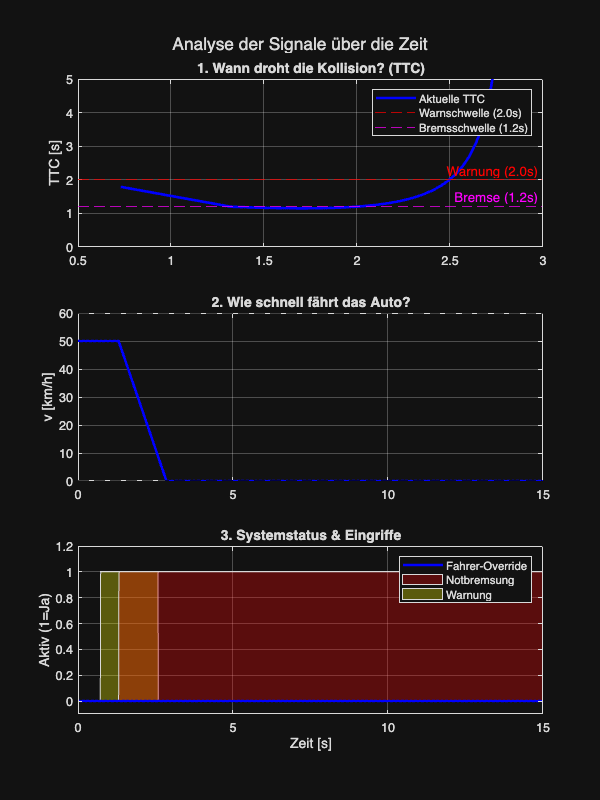


% Auswertungen der Zeitdaten 
figure('Name', 'AEB Analyse - Zeitdaten', 'Position', [50 50 600 800]);
sgtitle('Analyse der Signale über die Zeit');

% Plot 1: TTC
subplot(3,1,1);
plot(zeit, ttc_werte, 'b', 'LineWidth', 2); hold on;
yline(ttc_warnung, 'r--', 'Warnung (2.0s)');
yline(ttc_bremse, 'm--', 'Bremse (1.2s)');
ylim([0 5]); grid on;
ylabel('TTC [s]'); title('1. Wann droht die Kollision? (TTC)');
legend('Aktuelle TTC', 'Warnschwelle (2.0s)', 'Bremsschwelle (1.2s)', 'Location', 'northeast');

% Plot 2: Geschwindigkeit
subplot(3,1,2);
plot(zeit, auto_geschwindigkeit*3.6, 'b', 'LineWidth', 2); hold on;
yline(v_min*3.6, 'k--'); yline(v_max*3.6, 'k--');
grid on;
ylabel('v [km/h]'); title('2. Wie schnell fährt das Auto?');

% Plot 3: Status
subplot(3,1,3);
area(zeit, warnung_aktiv, 'FaceColor', 'y', 'FaceAlpha', 0.3); hold on;
area(zeit, bremse_aktiv, 'FaceColor', 'r', 'FaceAlpha', 0.3);
plot(zeit, driver_override_aktiv, 'b', 'LineWidth', 2); 
ylim([-0.1 1.2]); grid on;
ylabel('Aktiv (1=Ja)'); xlabel('Zeit [s]');
title('3. Systemstatus & Eingriffe');
legend('Warnung', 'Notbremsung', 'Fahrer-Override', 'Location', 'northeast');

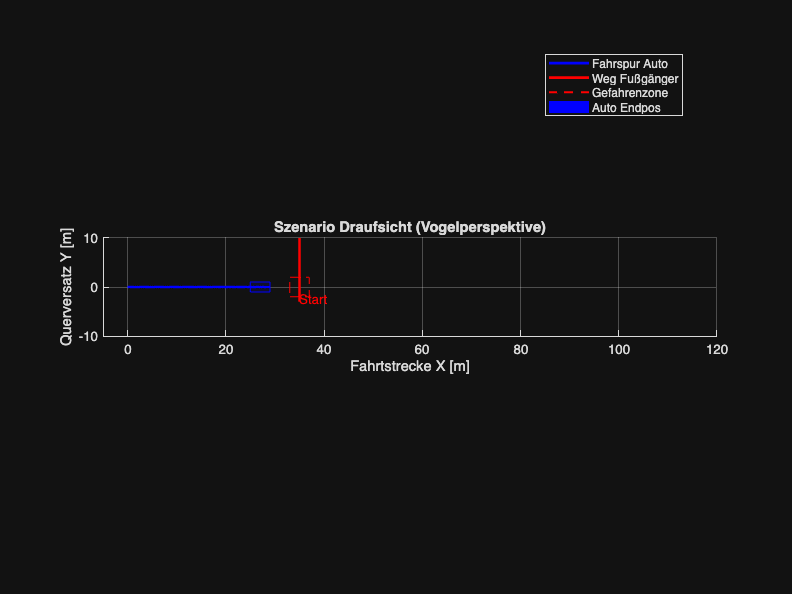


% FENSTER 2: SZENARIO
figure('Name', 'AEB Szenario - Trajektorie', 'Position', [660 50 800 600]);
hold on; grid on; axis equal;

% Auto Fahrspur (h1)
h1 = plot(auto_position_x, auto_position_y, 'b-', 'LineWidth', 2);

% Fußgänger Weg (h2)
h2 = plot(pedestrian_position_x, pedestrian_position_y, 'r-', 'LineWidth', 2);
text(pedestrian_position_x(1), pedestrian_position_y(1)+0.5, 'Start', 'Color', 'r');

% Gefahrenzone 
rectangle('Position', [pedestrian_x-2, -2, 4, 4], 'EdgeColor', 'r', 'LineStyle', '--');
h3 = plot(NaN, NaN, 'r--', 'LineWidth', 1.5); 

% Auto Endposition 
last_x = auto_position_x(end);
rectangle('Position', [last_x-4, -1, 4, 2], 'FaceColor', 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b');
h4 = plot(NaN, NaN, 'b-', 'LineWidth', 10, 'Color', [0 0 1 0.2]); 

xlabel('Fahrtstrecke X [m]'); ylabel('Querversatz Y [m]');
title('Szenario Draufsicht (Vogelperspektive)');
xlim([-5 120]); ylim([-10 10]);

legend([h1, h2, h3, h4], ...
       'Fahrspur Auto', ...
       'Weg Fußgänger', ...
       'Gefahrenzone', ...
       'Auto Endpos', ...
       'Location', 'best');



% Hilfsfunktionen

function [system_aktiv] = pruefe_geschwindigkeitsbereich(v, v_min, v_max)
    system_aktiv = (v >= v_min && v <= v_max);
end

function [ttc] = berechne_ttc(auto_x, auto_v, ped_x, ped_y)
    dx = ped_x - auto_x;
    dy = abs(ped_y); 
    if dy < 2.0 && dx > 0
        if auto_v > 0
            ttc = dx / auto_v;
        else
            ttc = Inf;
        end
    else
        ttc = Inf;
    end
end

function [warnung_neu] = kollisionswarnung(warnung_alt, ttc, ttc_warnung)
    if ttc <= ttc_warnung && ~warnung_alt
        warnung_neu = true;
    elseif ttc > ttc_warnung + 0.5
        warnung_neu = false;
    else
        warnung_neu = warnung_alt;
    end
end

function [bremse_neu, bremskraft_neu] = notbremsung(bremse_alt, bremskraft_alt, ttc, ttc_bremse, bremskraft_min, override)
    
    % 1. Fahrer-Override
    if override
        if bremse_alt
            fprintf('INFO: Notbremsung durch Fahrer abgebrochen!\n');
        end
        bremse_neu = false;
        bremskraft_neu = 0;
        return; 
    end

    % 2. START der Bremsung
    if ttc <= ttc_bremse && ~bremse_alt
        bremse_neu = true;
        bremskraft_neu = bremskraft_min;
        fprintf('ACHTUNG: Notbremsung eingeleitet (TTC=%.2fs)\n', ttc);
        
    % 3. Bremsung halten
    elseif bremse_alt
        bremse_neu = true;
        bremskraft_neu = bremskraft_alt;
        
    % 4. Sonst: Alles aus
    else
        bremse_neu = false;
        bremskraft_neu = 0; 
    end
end